# Position and Attitude Control of a Quadcopter

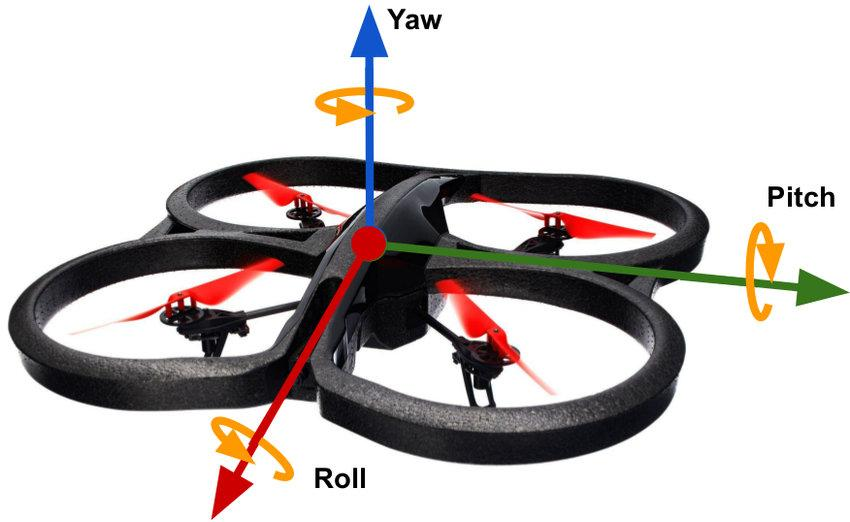

## Nomenclature

	Inertial frame								$\bar{N} = \{\hat{x}_N, \hat{y}_N, \hat{z}_N\}$

	Body frame								$\bar{B} = \{\hat{x}_B, \hat{y}_B, \hat{z}_B\}$

	Thrust constant							$K_t  \; [kg\cdot m\;/\;rad]$

	Body mass								$mass \; [kg]$

	Gravity constant							$g \; [m/s^2]$

	Wing length								$l \; [m]$

	Inertia matrix								$I_b \; [kg \cdot m^2]$

	Propeller Thrust vector						$T_p \; [N]$ 

	Propeller Torque vector						$\tau_p \; [N\cdot m]$

	Position vector							$r  \; [m]$ 

	Velocity vector 							$\dot{r} \; [m/s]$

	Attitude of Body as DCM 					$R_{BN} = R_{NB}^T$

	Attitude of Body as Euler Angles	 			$q \; [rad]$

	Rotational velocity of Body w.r.t Inertial frame	$\omega \; [rad/s]$

***pre-superscript denotes the frame a vector is defined in***

## Parameters

close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
d = -1e-3 * diag([1 1 1.75]);

## Dynamics

let the torque kinematics (transform from input to angular acceleration) be

        
$$\tau_k = \pmatrix{1 & 0 & -1 & 0 \cr 0 & -1 & 0 & 1 \cr -1 & 1 & -1 & 1}$$
 

Forces:

	
$$^NT_p = R_{NB}\;\hat{z}_{B}\; K_t \Sigma^4_{i=1}u_i^2$$


	
$$^B\tau_p = K_t \;l\;\tau_k\;u^Tu$$


	
$$^NF_g = -massg \hat{z}_N$$


	
$$^NF_w = w_1\hat{x}_N + w_2\hat{y}_N + w_3\hat{z}_N$$


	
$$^B\tau_w = g_1\hat{x}_N + g_2\hat{y}_N + g_3\hat{z}_N$$


	
$$^NF_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; ^N\dot{r}$$
 

	
$$^B\tau_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; \omega$$
 

EOM:

        $\ddot{r} = (T_p + F_g )\; / \; mass$  **Just realized I need to be dividing by the mass (it's pretty late)

        
$$\dot{\omega} = I^{-1}(-[\tilde{\omega}]I\omega +\tau)$$
 

As a state-space model

Let $X = \pmatrix{r \cr \dot{r} \cr q \cr \omega}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = T_p + F_g + F_w + F_d$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} = I_b^{-1}(-[\tilde{x_4}]\bar{I}x_4+\tau_p + \tau_w + \tau_d)$$


The dynamics can also be linearized about the zero-attitude (hover state)

    
$$^NT_p = \hat{z}_{N}\; K_t \Sigma^4_{i=1}u_i$$


    
$$^B\tau_p = K_t \;l\;\tau_k u$$


Let $X = \pmatrix{r \cr \dot{r} \cr q \cr \omega}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = T_p + F_g + F_w$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} =I_b^{-1}(\tau_p + \tau_w + \tau_d)$$


As a state space model:

m = 4;			% number of inputs
n = 4;			% number of states 4 (vectors)
state_dim = 3;	% dimension of each state


z = [0; 0; 1];
Z = [z z z z];
Xo = [0; 0; 0];
I = eye(state_dim);
O = zeros(state_dim, state_dim);

tau_k = [1  0 -1  0;
	     0 -1  0  1;
		-1  1 -1  1];

A = [O I O O;						% block size (state_dim, state_dim)
	 O O O O;
	 O O O I;
	 O O O O];

O = zeros(state_dim, m);

B = Kt *[O; Z; O; l * tau_k];		% block size (state_dim, n_inputs) ignore non-controlled forces

C = eye(n * state_dim);
D = 0;

G = ss(A, B, C, D);

## Analysis

### Non Linear Control Law

[Kref, Kfb, Kff] = Rufous_og_controller(Kt, mass, g, [0; 0; 0], 20, 100, 0, 0, 0);
L = G * Kfb;
S = 1 / (eye(12) + L);
T = minreal(L * S);

28 states removed.



mag_range = [1e-3 1e6];
freq_range = [1e-20 1e5];

WI = makeweight(0.01, [1, 0.5], 10);

Hinf_norm_t = norm(T, 'inf')

Hinf_norm_t = 3.1733e+08

robust_stability_of_og_controller = norm(WI * T, 'inf')

robust_stability_of_og_controller = 3.4092e+07


figure, hold on
h = sigmaplot(T, 'b', WI^-1, 'r--');

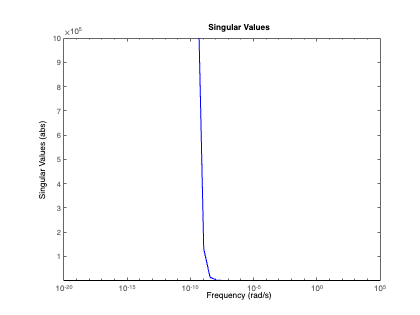

plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range, 'Ylim', mag_range);

## Simulation

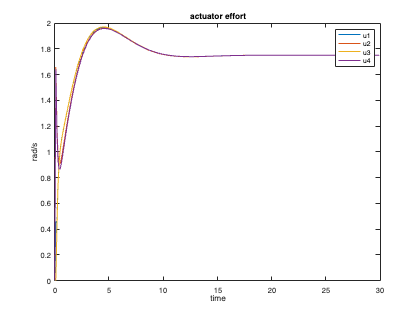

max_time = 30;
n_samples = max_time / 0.001;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% histories
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
rddot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
qr_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
omegadot_hist = zeros(3, n_samples);

qr_ext = [0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 1 0 0 0];

% set initial conditions
r_r = [1; 0; 1];
r_hist(3, 1) = 2;
q_hist(1, 1) = -0.17;
q_hist(3, 1) = -0.6 * pi;
omega_hist(1, 1) = -0.1;
u_hist(:, 1) = zeros(4, 1);

for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), Kt, mass, g, l, Ib);

	% update control
	R = [r_r; 0; 0; 0; 0; 0; 0; 0; 0; 0];
	X = [r_hist(:, i); rdot_hist(:,i); q_hist(:,i); omega_hist(:,i)];
	[Kref, Kfb, Kff] = Rufous_og_controller(Kt, mass, g, [0; 0; 0], 40, 75, 0.15, 1, 50);

	% update states
	u_hist(:, i + 1) = Kff + (Kfb * Kref * (R - X));
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = wrap_angle(q_hist(:, i) + (dq * dt));
	qr_hist(:, i + 1) = qr_ext * (Kref * (R - X));
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	V = norm(Kref * (R - X));

	if V > 1e150
		fprintf("Breaking for %d at %i", V, i);
		fprintf("Omega %d %d %d", omega_hist(1, i), omega_hist(2, i), omega_hist(3, i));
		break;
	end

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

figure
plot(t_space(1:100:end), max(u_hist(:, 1:100:end), [0; 0; 0; 0]))
title("actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

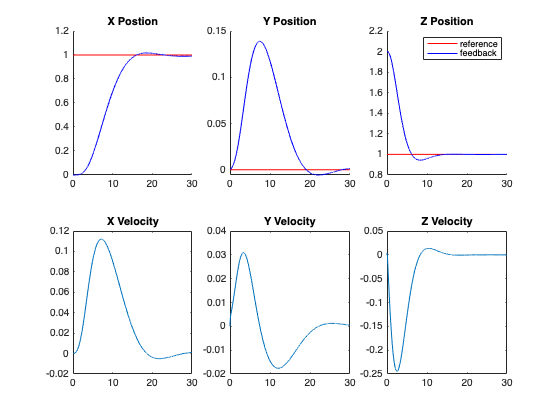


figure
title("Position history")
% draw_position_history(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, 100);
position_titles = ["X Postion" "Y Position" "Z Position" "X Velocity" "Y Velocity" "Z Velocity"];
plot_vectors(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, position_titles, 5);

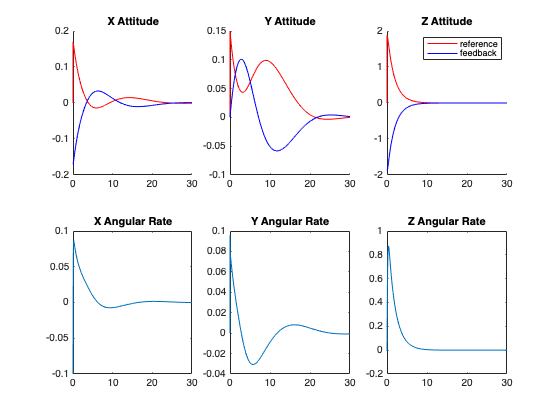


figure
title("Attitude history")
attitude_titles = ["X Attitude" "Y Attitude" "Z Attitude" "X Angular Rate" "Y Angular Rate" "Z Angular Rate"];
plot_vectors(t_space, q_hist, omega_hist, qr_hist, attitude_titles, 1);